Example:

Define S, the DFT of a signal s.

Cmpute the orginal signal by taking the inverse DFT

Gnerate the magnitude and phase plot

S = [4 5 2 6 8 4 2 0];
s = ifft(S)

s =    3.8750 + 0.0000i  -0.9419 + 0.6187i   1.0000 + 0.3750i  -0.0581 + 0.6187i   0.1250 + 0.0000i  -0.0581 - 0.6187i   1.0000 - 0.3750i  -0.9419 - 0.6187i


%plot the signal
stem(abs(s))
title('signal')

%create magnitude and phase plots for S
stem(abs(S))
title('magnitude of DFT')

stem(angle(S))
title('phase of DFT')

- in the magnitude plot we have symmetry. Point 1and N-1, 2 and N-2, k and N-k. There magnitudes will be equivelent

- in the phase plot there is antisymmetry x = -x

- Odd number of pints due to axis of symmetry is inbetween 2 points

To do:  

Define a signal, x.

Compute X, the DFT of x, using the fft command. the inverse DFT.  

Generate the magnitude and phase plots of X.

List observations at whiteboard (i.e. do you observe any symmetries, etc?)


x = [4 5 2 6 8 4 2 0];
X = fft(x)

X =   31.0000 + 0.0000i  -7.5355 - 4.9497i   8.0000 - 3.0000i  -0.4645 - 4.9497i   1.0000 + 0.0000i  -0.4645 + 4.9497i   8.0000 + 3.0000i  -7.5355 + 4.9497i



%plot signal
stem(abs(x))
title('signal')

% inverse magnitude and phase plot
stem(abs(X))
title('inverse magnitude of DFT')

stem(angle(X))
title('inverse phase of DFT')

To do

Read in the signal from your Nyquist Lab

Generate the magnitude and phase plots of this signal

Adjust the range to see individual peaks

List any observations at the whiteboard

[data,fs]=audioread('03 - The Andy Griffith Show.mp3');
x1 = data;
X1 = fft(x1)

X1 = 	1.0e+03 *

  -0.0257 + 0.0000i  -0.0363 + 0.0000i
  -0.0010 - 0.0057i  -0.0021 - 0.0042i
   0.0007 + 0.0005i  -0.0055 + 0.0014i
  -0.0004 + 0.0005i  -0.0006 - 0.0004i
   0.0013 + 0.0001i  -0.0020 + 0.0004i
  -0.0001 + 0.0019i   0.0027 - 0.0008i
  -0.0011 + 0.0003i  -0.0026 - 0.0023i
   0.0032 + 0.0048i   0.0014 + 0.0001i
   0.0010 - 0.0005i  -0.0022 + 0.0011i
   0.0006 - 0.0018i   0.0029 + 0.0005i


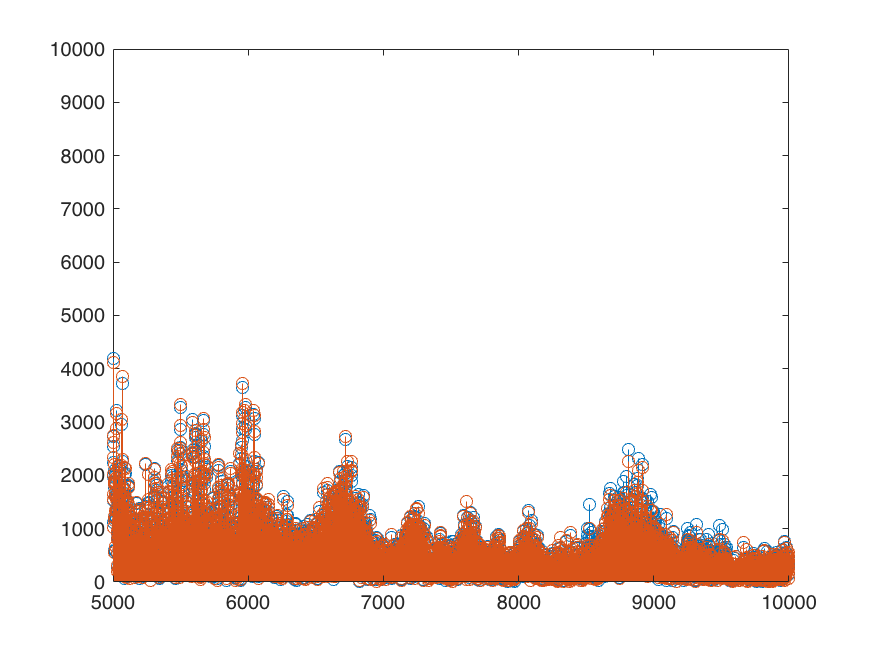

stem(abs(X1))
axis([5000 10000 0 10000])

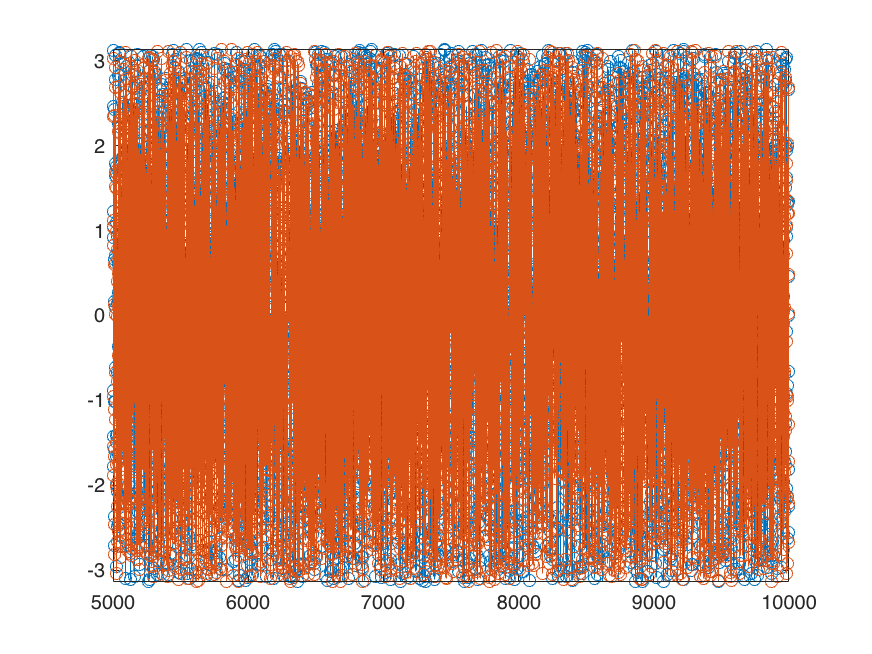

stem(angle(X1))
axis([5000 10000 -3.14 3.14])